# Aufgabe 2: Temperaturmessung

## Einlesen von Daten

clear;
close all;

Data = load("Messdaten.txt");
Zeit = Data(:,1);
T_Messobjekt = Data(:,2);
T_Umgebung = Data(:,3);


## Funktionen plotten

% wir verfugen uber alle benotigten Messwerte fur den ersten Plot, und
% erzeugen ihn mit folgenden Befehle:
subplot(2,1,1); 
plot(Zeit, T_Messobjekt, Zeit, T_Umgebung); grid on;
xlabel('Zeit'), ylabel('Temperatur')
ylim([23, 37])
legend(["Messobjekt","Umgebung"],'Location','best')

%Fur den 2. Plot werden neue Parameter und eine Funktion f(Zeit) benotigt.
%Wir definieren sie folgendermase:
a = 10; b = -0.01;

a =11

a = 11

b = -0.004

b = -0.0040

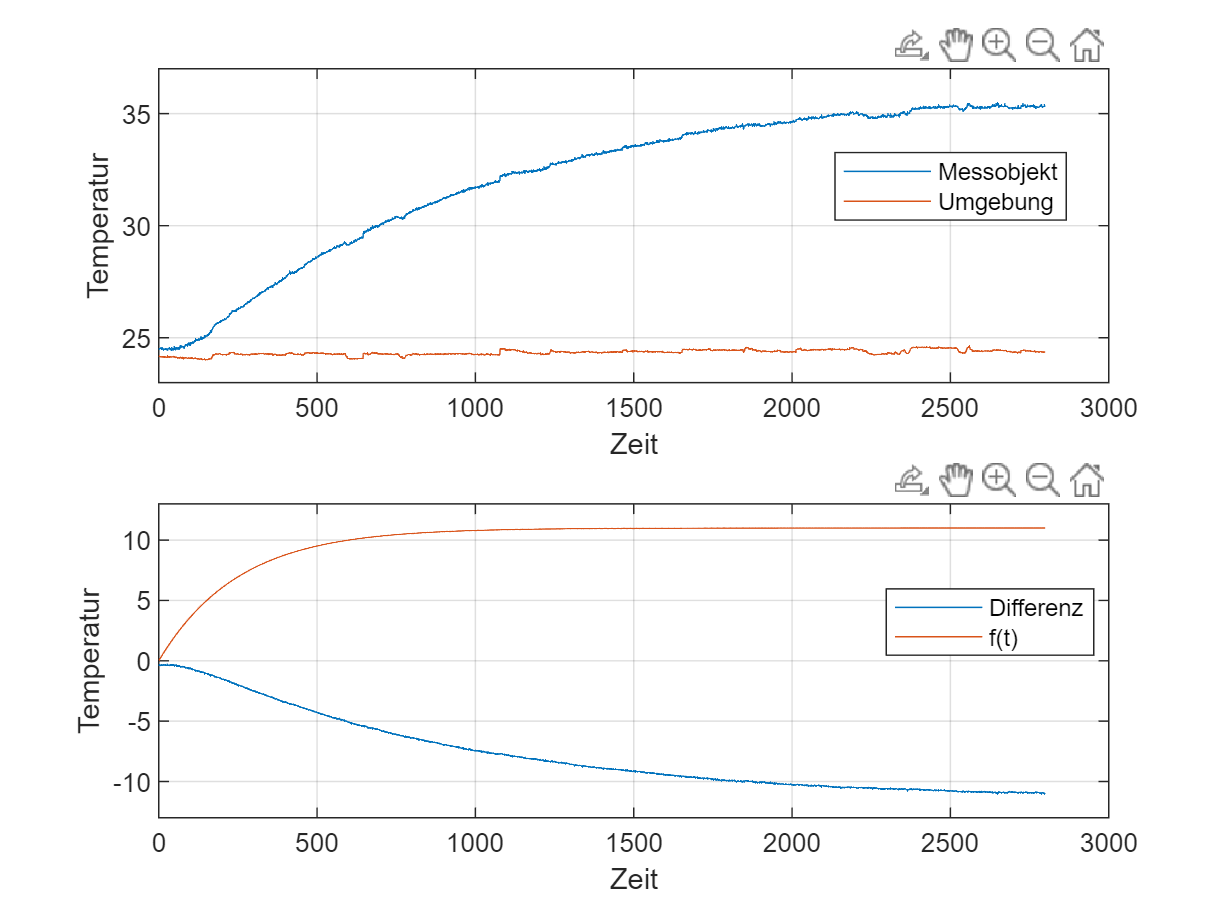

f = @(x) a * (1 - exp(b .* x));

subplot(2,1,2); plot(Zeit, T_Umgebung - T_Messobjekt, Zeit, f(Zeit)); grid on;
xlabel('Zeit'), ylabel('Temperatur')
ylim([-13, 13])
legend(["Differenz","f(t)"],'Location','best')

a =5

a = 5

b = 0

b = 0